# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha: 17/11/2026**

# Tema 4. Ejercicio 4. Características locales y texturas

## Localización de esquinas utilizando el algoritmo FAST

El objetivo de esta práctica es comprobar el comportamiento del detector FAST para localizar esquinas en diferentes tipos de imágenes. Para ello:

- Utilice `corners = detectFASTFeatures(I)` sobre la imagen 'ladrillos1.jpg', y visualice las esquinas sobre ella con la instrucción 

**strongestCorners = corners.selectStrongest(25);**

**plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5)**;

- Aumente el número de esquinas seleccionadas y visualizadas para comprobar que las que se incorporan tienen una respuesta menor que las iniciales.

- Pruebe sobre diferentes imágenes (texture-pattern2.png, rice.tif, etc.) para identificar aquellas en las que estas características pueden resultar más útiles.

JUSTIFICACION: Fast es más útil en imágenes con muchas esquinas bien marcadas, como `texture-pattern2` o los ladrillos, porque los puntos que detecta caen en esquinas reales. En `rice` los granos son redondeados y casi no tienen esquinas, así que los puntos son pocos y menos fiables.

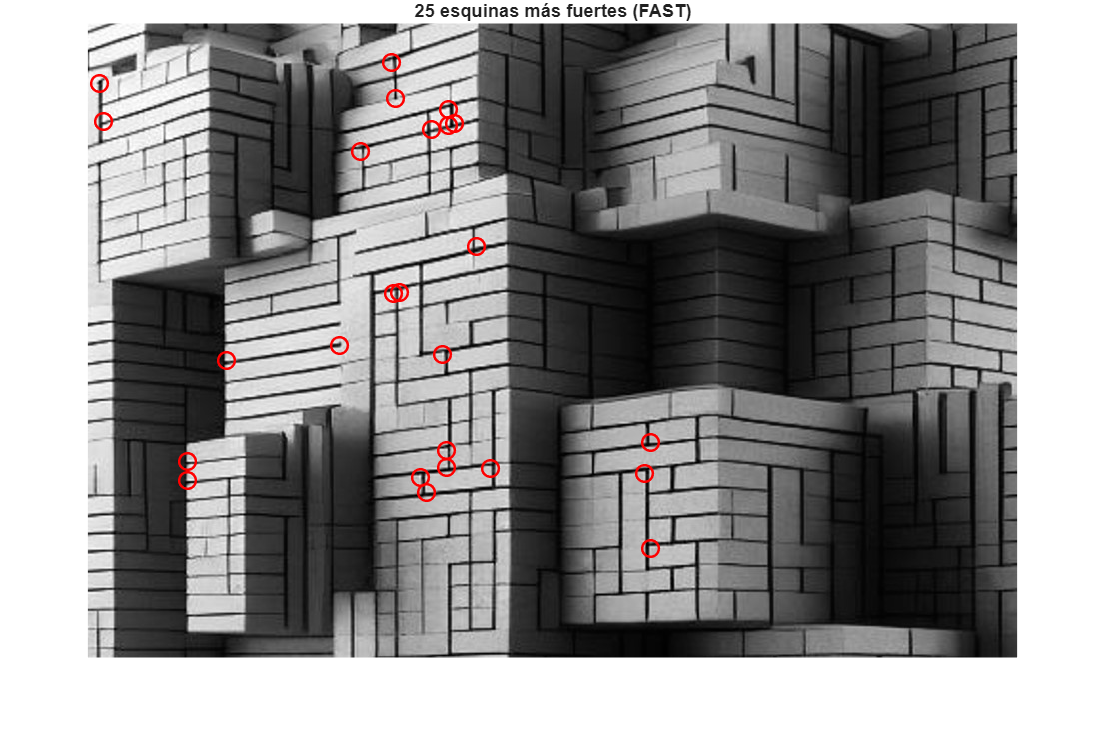

I = imread('ladrillos1.jpg');
I = rgb2gray(I);
corners = detectFASTFeatures(I);
strongestCorners = corners.selectStrongest(25);
figure
imshow(I)
hold on
plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
title('25 esquinas más fuertes (FAST)');

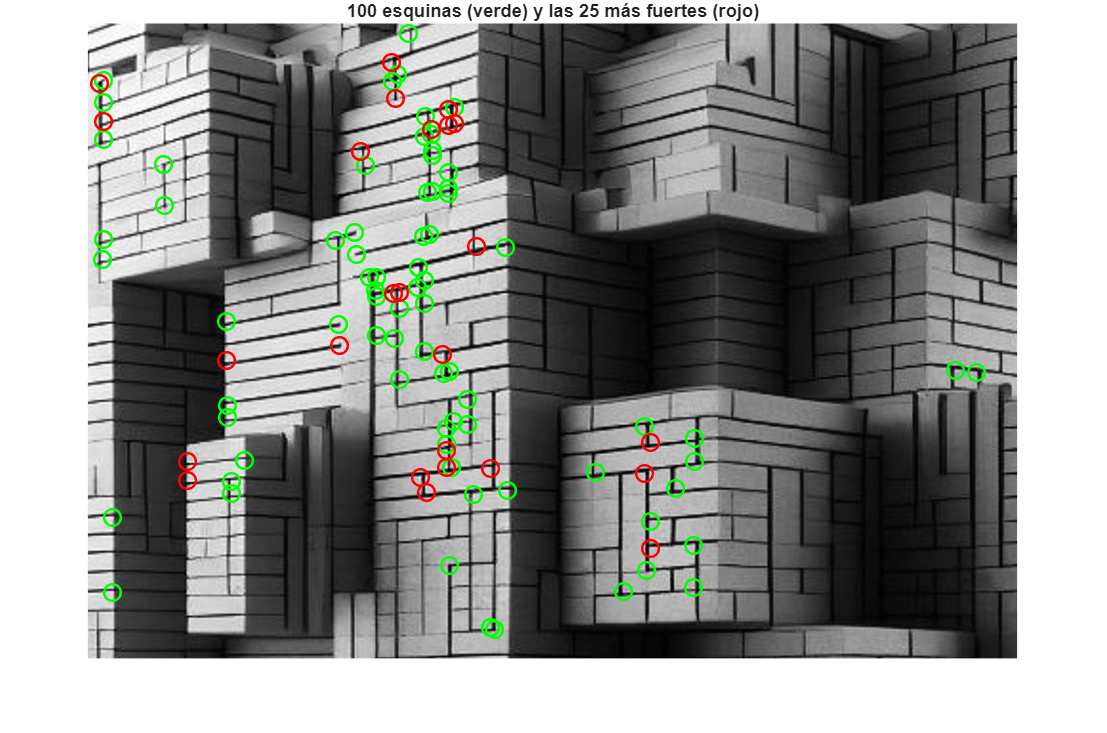


strongestCorners100 = corners.selectStrongest(100);
figure
imshow(I)
hold on
plot(strongestCorners100.Location(:,1), strongestCorners100.Location(:,2), 'go', 'MarkerSize', 10, 'LineWidth', 1.5);
plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
title('100 esquinas (verde) y las 25 más fuertes (rojo)');

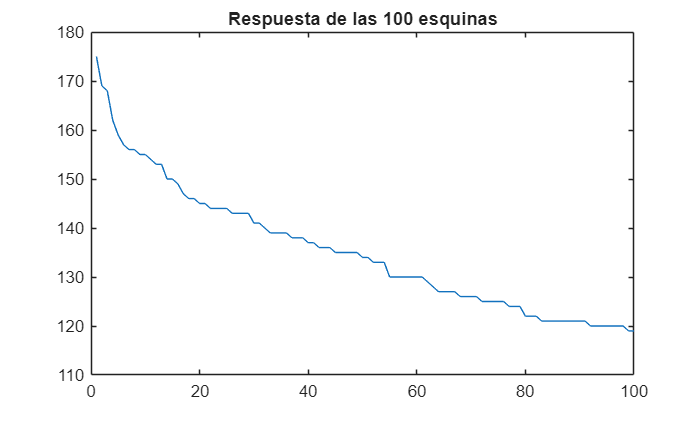

figure
plot(strongestCorners100.Metric)
title('Respuesta de las 100 esquinas');

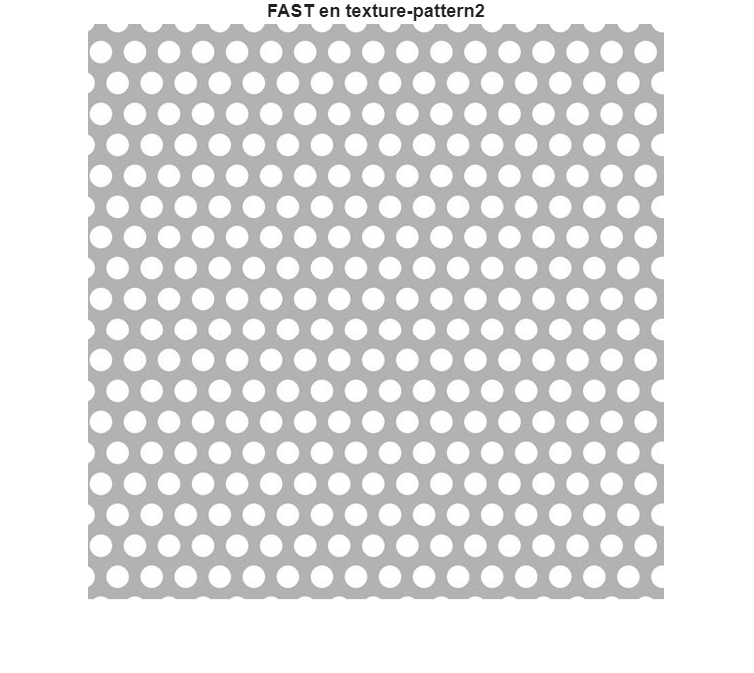


I2 = imread('texture-pattern2.png');
if size(I2,3) == 3
    I2 = rgb2gray(I2);
end
corners2 = detectFASTFeatures(I2);
strongestCorners2 = corners2.selectStrongest(100);
figure
imshow(I2)
hold on
plot(strongestCorners2.Location(:,1), strongestCorners2.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
title('FAST en texture-pattern2');

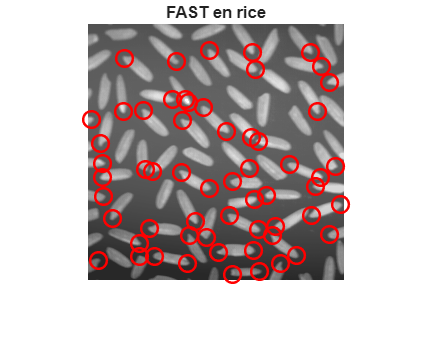


I3 = imread('rice.tif');
corners3 = detectFASTFeatures(I3);
strongestCorners3 = corners3.selectStrongest(100);
figure
imshow(I3)
hold on
plot(strongestCorners3.Location(:,1), strongestCorners3.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
title('FAST en rice');

## Uso de características LBP para distinguir imágenes con texturas diferentes

El objetivo de este ejercicio es verificar el comportamiento de las caracteristicas LBP en imágenes con texturas diferentes. Para ello:

- Abra y muestre las imágenes texture-canvas.png, gotas.jpg, ladrillos2.jpg, ladrillos3.jpg y ladrillos4.jpg y calcule sus características LBP con la instrucción `LBPImag1 = extractLBPFeatures(Imag1,'Upright',false).`Utilice `'Upright',false` para obtener la variante invariante a rotación de LBP estudiada en teoría.

- Visualice las características con `bar(LBPImag1)`. ¿Se parecen entre sí las características de las distintas imágenes? Utilice la función subplot para visualizar todas las imágenes y características y así poder realizar la comparación fácilmente.

JUSTIFICACION: Las de los ladrillos se parecen mucho entre sí: `ladrillos3` y `ladrillos4` son prácticamente iguales y `ladrillos2` es muy parecida. `gotas` es la más distinta, porque tiene un pico muy alto en una barra, y `canvas` queda en un punto intermedio.

- Calcule la distancia entre las características LBP de ladrillos3.jpg y cada una de las demás imágenes, utilizando la instrucción `DistImag1_2 = norm (LBPImag1 - LBPImag2)`. Compare las distancias obtenidas. ¿Son coherentes con la similitud que se aprecia visualmente entre las texturas? Justifique la respuesta.

JUSTIFICACION: Sí. La distancia más pequeña es con `ladrillos4`, casi 0, porque es la misma pared girada y la LBP con `'Upright',false` es invariante a rotación. Después viene `ladrillos2`, que también son ladrillos, luego `canvas`, y la más grande es `gotas`, que es la textura que menos se parece.

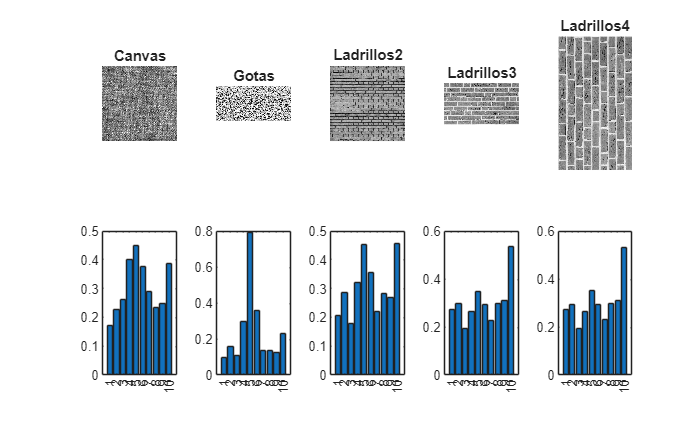

Imag1 = imread('Texture-canvas.png');
Imag2 = imread('Gotas.jpg');
Imag2 = rgb2gray(Imag2);
Imag3 = imread('Ladrillos2.jpg');
Imag3 = rgb2gray(Imag3);
Imag4 = imread('Ladrillos3.jpg');
Imag4 = rgb2gray(Imag4);
Imag5 = imread('Ladrillos4.jpg');
Imag5 = rgb2gray(Imag5);

LBPImag1 = extractLBPFeatures(Imag1,'Upright',false);
LBPImag2 = extractLBPFeatures(Imag2,'Upright',false);
LBPImag3 = extractLBPFeatures(Imag3,'Upright',false);
LBPImag4 = extractLBPFeatures(Imag4,'Upright',false);
LBPImag5 = extractLBPFeatures(Imag5,'Upright',false);

figure
subplot(2,5,1); imshow(Imag1); title('Canvas');
subplot(2,5,2); imshow(Imag2); title('Gotas');
subplot(2,5,3); imshow(Imag3); title('Ladrillos2');
subplot(2,5,4); imshow(Imag4); title('Ladrillos3');
subplot(2,5,5); imshow(Imag5); title('Ladrillos4');
subplot(2,5,6); bar(LBPImag1);
subplot(2,5,7); bar(LBPImag2);
subplot(2,5,8); bar(LBPImag3);
subplot(2,5,9); bar(LBPImag4);
subplot(2,5,10); bar(LBPImag5);


DistImag4_1 = norm(LBPImag4 - LBPImag1)

DistImag4_1 = single
0.2995

DistImag4_2 = norm(LBPImag4 - LBPImag2)

DistImag4_2 = single
0.6500

DistImag4_3 = norm(LBPImag4 - LBPImag3)

DistImag4_3 = single
0.1753

DistImag4_5 = norm(LBPImag4 - LBPImag5)

DistImag4_5 = single
0.0040